%% 0) Paths
healthyPath = "C:\Users\DELL\Downloads\Wind_Turbine_Data\Healthy";
damagedPath = "C:\Users\DELL\Downloads\Wind_Turbine_Data\Damaged";
allFolders  = [healthyPath, damagedPath];

%% 1) Create the signal datastore with a faster ReadFcn
% Try common variable names first; only fallback to scan.
likelyVars = ["acc","data","signal","X","S","Y"];  % <- edit if you know the names
readFcn = @(p) fastLoadMatrix(p, likelyVars);      % helper below

ds = signalDatastore(allFolders, ...
    'IncludeSubfolders', true, ...
    'FileExtensions', '.mat', ...
    'ReadFcn', readFcn);

filePaths = ds.Files;

%% 2) Read into memory (optional—but faster loader helps)
tic
sigdata = readall(ds);   % 1×N cell
toc

Elapsed time is 25.578423 seconds.



assert(~isempty(sigdata), 'No signals were read. Check paths and extensions.');

%% 3) Labels from parent folder
labels = arrayfun(@(p) string(getParentFolder(p{1})), filePaths, 'UniformOutput', true);
labels = categorical(labels);

% Quick label summary
disp('Label distribution:');

Label distribution:


disp(summary(labels));

          Size: [20 1]
          Type: 'categorical'
    Categories: {2×1 cell}
        Counts: [2×1 double]
    NumMissing: 0




%% (Optional) PLOTS — disable for speed
doPlot = false;
if doPlot
    figure, plot(sigdata{1}), title('Example Signal #1'), grid on
    if numel(sigdata) >= 2
        figure, s2 = sigdata{2};
        plot(s2(1:min(5000,size(s2,1)), :)); title('Example Signal #2 (first 5k samples)'); grid on
    end
end

%% 7) Stratified Train/Val/Test split
rng(42);
idxAll      = (1:numel(labels))';
classes     = categories(labels);
trainMask   = false(size(idxAll));
valMask     = false(size(idxAll));
testMask    = false(size(idxAll));

trainRatio = 0.80;
valRatio   = 0.10;

for c = 1:numel(classes)
    idxC = idxAll(labels == classes{c});
    nC   = numel(idxC);
    nTrain = max(1, floor(trainRatio*nC));
    nVal   = max(0, floor(valRatio*nC));
    idxPerm = idxC(randperm(nC));
    iTrain  = idxPerm(1:nTrain);
    iVal    = idxPerm(nTrain+1 : min(nTrain+nVal, nC));
    iTest   = setdiff(idxPerm, [iTrain; iVal]);
    trainMask(iTrain) = true;  valMask(iVal) = true;  testMask(iTest) = true;
end

traindata   = sigdata(trainMask);
valdata     = sigdata(valMask);
testdata    = sigdata(testMask);
trainlabels = labels(trainMask);
vallabels   = labels(valMask);
testlabels  = labels(testMask);
fprintf('Train: %d | Val: %d | Test: %d\n', numel(traindata), numel(valdata), numel(testdata));

Train: 16 | Val: 2 | Test: 2



%% 9) PREP: orient to [8 × T], standardize, and FIX LENGTH once
% Choose a fixed sequence length that fits memory & physics (e.g., 4096 or 8192)
Tfixed = 4096;   % <-- tune for your sampling rate & desired window

% Start a parallel pool (speeds up prep for many files)
p = gcp('nocreate');
if isempty(p)
    try, parpool('threads'); catch, parpool; end
end

Xtr = cell(size(traindata));  Xva = cell(size(valdata));  Xte = cell(size(testdata));

% Parallelize preprocessing (faster than cellfun on large sets)
tic
parfor i = 1:numel(traindata)
    Xtr{i} = prepOneFast(traindata{i}, Tfixed);
end
parfor i = 1:numel(valdata)
    Xva{i} = prepOneFast(valdata{i}, Tfixed);
end
parfor i = 1:numel(testdata)
    Xte{i} = prepOneFast(testdata{i}, Tfixed);
end
toc

Elapsed time is 1.274520 seconds.



% Align label categories
cats = categories(labels);
trainlabels = categorical(string(trainlabels), cats);
vallabels   = categorical(string(vallabels),   cats);
testlabels  = categorical(string(testlabels),  cats);

if ~isempty(Xtr)
    fprintf("Example prepared size (Train 1): %s  [channels × time]\n", mat2str(size(Xtr{1})));
end

Example prepared size (Train 1): [8 4096]  [channels × time]


Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:15 |       62.50% |       50.00% |       0.6749 |       0.7050 |          0.0010 |
|      10 |          10 |       00:02:09 |       43.75% |       50.00% |       0.6222 |       0.4484 |          0.0010 |
|      20 |          20 |       00:03:59 |       81.25% |       50.00% |       0.6233 |       1.6403 |          0.0010 |
|======================================================================================================================|
Training

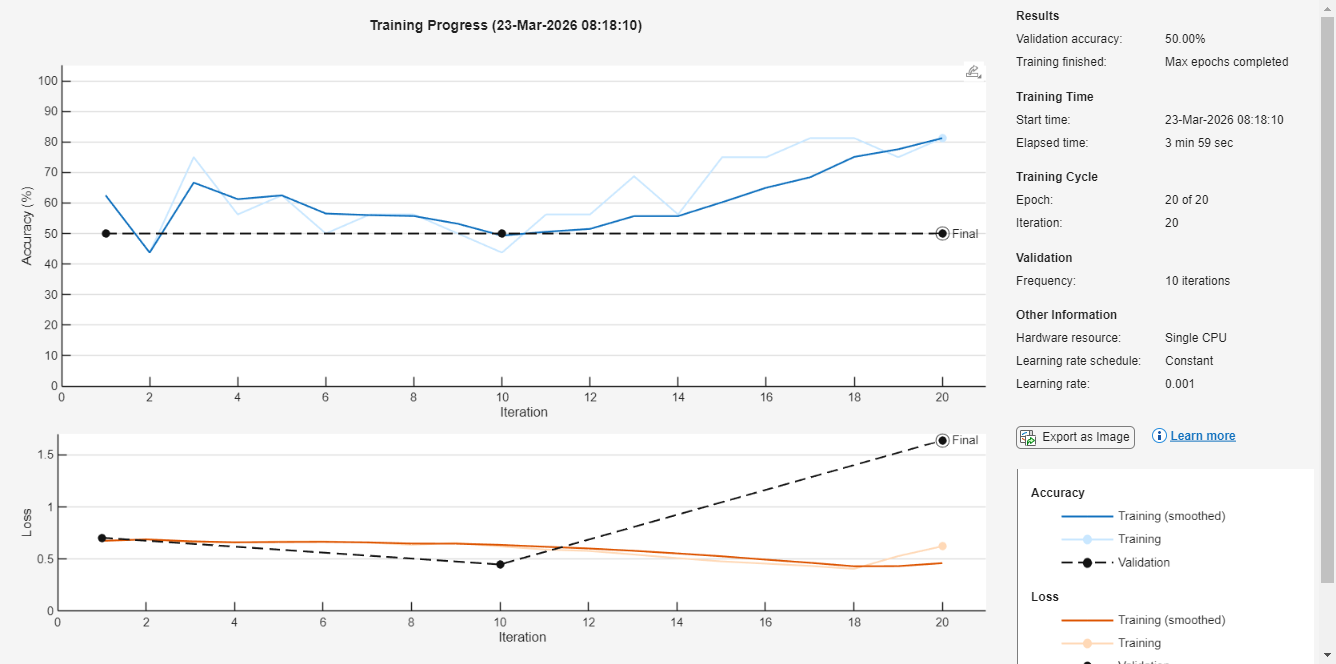


%% 10) Define LSTM and training options (single definition)
numFeatures = 8;
numClasses  = numel(cats);
layers = [
    sequenceInputLayer(numFeatures, "Name","input")
    lstmLayer(128, "OutputMode","last", "Name","lstm")
    dropoutLayer(0.5, "Name","drop")
    fullyConnectedLayer(numClasses, "Name","fc")
    softmaxLayer("Name","sm")
    classificationLayer("Name","cls")
];

% Use GPU if available, larger batch, and fixed sequence length for speed
opts = trainingOptions("adam", ...
    "InitialLearnRate", 1e-3, ...
    "MaxEpochs", 20, ...
    "MiniBatchSize", 32, ...                 % larger batch for throughput
    "Shuffle", "every-epoch", ...
    "ValidationData", {Xva, vallabels}, ...
    "ValidationFrequency", 10, ...
    "ExecutionEnvironment","auto", ...       % GPU if available
    "DispatchInBackground", true, ...        % prefetch next batch
    "SequenceLength", Tfixed, ...            % skip dynamic padding each batch
    "SequencePaddingDirection","right", ...
    "SequencePaddingValue", 0, ...
    "Plots", "training-progress", ...
    "Verbose", true);

%% 11) Train
[net_1, trainInfo] = trainNetwork(Xtr, trainlabels, layers, opts);

save('net_1.mat', 'net_1', 'trainInfo');

%% ---------- Helpers ----------
function mat = fastLoadMatrix(p, likelyVars)
    % Speed-first loader: try a short list of variable names, else fallback scan
    S = load(p);
    % Try likely names
    for k = 1:numel(likelyVars)
        vn = likelyVars(k);
        if isfield(S, vn) && isnumeric(S.(vn)) && ~isscalar(S.(vn)) && ndims(S.(vn)) == 2
            mat = S.(vn);
            return
        end
    end
    % Fallback: first numeric 2-D
    fn = fieldnames(S);
    for k = 1:numel(fn)
        v = S.(fn{k});
        if isnumeric(v) && ~isscalar(v) && ndims(v) == 2
            mat = v; return
        end
    end
    error('No numeric 2D matrix found in file: %s', p);
end

function parent = getParentFolder(p)
    [parentDir, ~, ~] = fileparts(p);
    [~, parent, ~] = fileparts(parentDir);
end

function Y = prepOneFast(X, Tfixed)
    X = toCxT(X);           % [C × T]
    X = keep8(X);           % [8 × T]
    X(~isfinite(X)) = 0;
    X = fixLength(X, Tfixed);  % crop/pad once here
    Y = zscoreChan(X);      % standardize per channel
end

function Y = toCxT(X)
    % If [time × channels], transpose to [channels × time]
    % Heuristic: time dimension is likely >> channels
    if size(X,1) >= size(X,2)
        Y = X.';  % transpose
    else
        Y = X;    % already [C × T]
    end
end

function Y = keep8(X)
    C = size(X,1); T = size(X,2);
    if C >= 8
        Y = X(1:8, :);
    else
        Y = [X; zeros(8-C, T, 'like', X)];
    end
end

function Y = fixLength(X, Tfixed)
    % Crop or right-pad with zeros to fixed T
    T = size(X,2);
    if T > Tfixed
        Y = X(:, 1:Tfixed);
    elseif T < Tfixed
        Y = [X, zeros(size(X,1), Tfixed - T, 'like', X)];
    else
        Y = X;
    end
end

function Z = zscoreChan(X)
    mu = mean(X, 2);
    sigma = std(X, 0, 2);
    sigma(sigma==0) = 1;
    Z = (X - mu) ./ sigma;
end

%% Safe GPU detection (no dot indexing unless available)
execEnv = "cpu";   % default

% Newer Deep Learning Toolbox has canUseGPU
if exist('canUseGPU','file') == 2
    if canUseGPU
        try
            d = gpuDevice();  % select default device
            fprintf('GPU detected: %s (CC %s, %d MB)\n', d.Name, d.ComputeCapability, d.TotalMemory/1024/1024);
            execEnv = "gpu";
        catch ME
            warning('GPU exists but not usable right now: %s', ME.message);
        end
    else
        warning('No usable GPU reported by canUseGPU(). Falling back to CPU.');
    end

% Fallback path for older releases without canUseGPU
elseif exist('gpuDeviceCount','file') == 2
    try
        n = gpuDeviceCount;
        if n > 0
            d = gpuDevice(1);
            fprintf('GPU detected: %s (CC %s, %d MB)\n', d.Name, d.ComputeCapability, d.TotalMemory/1024/1024);
            execEnv = "gpu";
        else
            warning('No GPU devices found by gpuDeviceCount(). Falling back to CPU.');
        end
    catch ME
        warning('GPU query failed: %s. Falling back to CPU.', ME.message);
    end
else
    warning('GPU functions not found (Parallel Computing Toolbox likely missing). Using CPU.');
end